U_old = 4.7336e+08

U_new = 9.6406e+07

e_old = 0

e_new = 0

val = Inf

rand
    <missing>    "vs"    "0.33705"



U_old = 4.7336e+08

U_new = 2.7693e+08

e_old = 0

e_new = 0

val = Inf

rand
    <missing>    "vs"    "0.53733"



U_old = 4.7336e+08

U_new = 8.1510e+08

e_old = 0

e_new = 0

val = 0

rand
    <missing>    "vs"    "0.9268"



U_old = 4.7336e+08

U_new = 7.9257e+08

e_old = 0

e_new = 0

val = 0

rand
    <missing>    "vs"    "0.4104"



U_old = 4.7336e+08

U_new = 9.6091e+09

e_old = 0

e_new = 0

val = 0

rand
    <missing>    "vs"    "0.37939"



U_old = 4.7336e+08

U_new = 2.9937e+09

e_old = 0

e_new = 0

val = 0

rand
    <missing>    "vs"    "0.041933"



U_old = 4.7336e+08

U_new = 1.0392e+08

e_old = 0

e_new = 0

val = Inf

rand
    <missing>    "vs"    "0.32145"



U_old = 4.7336e+08

U_new = 8.8354e+08

e_old = 0

e_new = 0

val = 0

rand
    <missing>    "vs"    "0.60027"



U_old = 4.7336e+08

U_new = 1.2829e+09

e_old = 0

e_new = 0

val = 0

rand
    <missing>    "vs"    "0.69972"



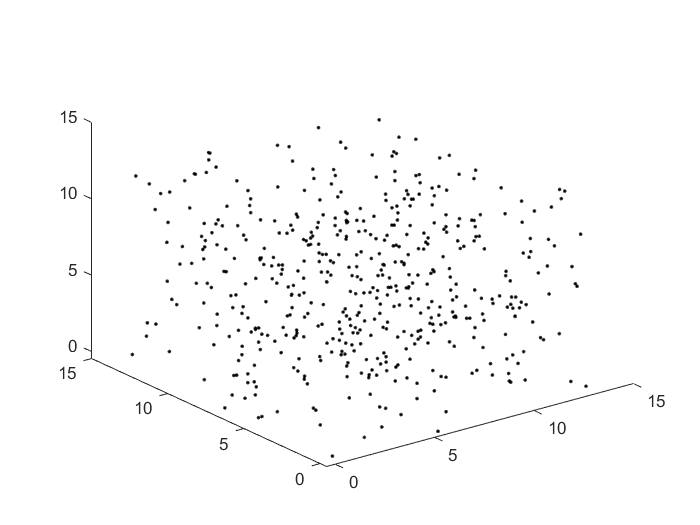

U_old = 4.7336e+08

U_new = 9.7132e+07

e_old = 0

e_new = 0

val = Inf

rand
    <missing>    "vs"    "0.45308"



%%% Question 1 %%%%
N = 500; rho_1 = 0.2; L = (N/rho_1)^(1/3); % particles, density, and length (from density)
sigma = 1; R = 0.1; epsilon = 1;                    % Cutoff distance, cutoff (particle radius), well depth
% Cutoff is temporary; technically not needed except for first iteration
% (will need to change)
T = 0.9; iterations = 10;                            % Setting iterations as 100 times for now    
Kb = 1.38064852 * 10^-23;                               % m2 kg s-2 K-1 
global B; B = 1/(Kb*T);                  % Not working?               % Repeat in each section?
[pos_hist, P_hist, vir_hist, U_hist] = MC_Project_Pipeline(N, R, L, T, sigma, epsilon, iterations, rho_1);

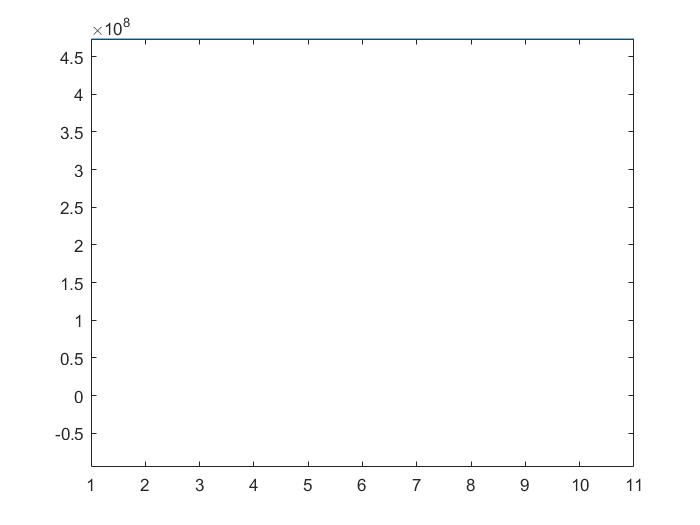

plot(U_hist);
maxU = max(U_hist); ylim([-0.2*maxU, maxU]); 

%%% Question 2 %%%
rho_2 = 0.1:0.1:1;
T_2 = [2,0.9];
for i = 1:length(T_2)
    T = T_2(i)
    P_rho = [];
    for j = 1:length(rho_2)
        rho = rho_2(j)
        [pos_hist, P_hist, vir_hist, U_hist] = MC_Project_Pipeline(N, R, L, T, sigma, epsilon, iterations, rho);
        P_avg = mean(P_hist); 
        P_rho = [P_rho, P_avg];
        %run monte carlo code, extract P(rho) and store in a matrix  
        j = j+1
    end
    %store matrix from inner for loop as variable for that temperature
    %(should end up with two)
    subplot(1, 2, i); 
    plot(rho_2, P_rho); 
    i = i+1
end
% plot P(rho) for T_2[1]
% plot P(rho) for T_2[2]
%answer: for which densities and temperatures you observe phase separation?